# Dummy maps for linear effects of stimlus intensity 

Model (6cond)

parameter:

- 6 Stimulus onset

- `    cue ``H``igh x stim ``H``igh (onset03_stim)`

- `    cue ``H``igh x stim ``M``ed`

- `    cue ``H``igh x stim ``L``ow`

- `    cue ``L``ow x stim ``H``igh`

- `    cue ``L``ow x stim ``M``ed`

- `    cue ``L``ow x stim ``L``ow`

- `C``ue: onset01_cue`

- `E``xpect rating: onset02_ratingexpect, pmod_expectRT`

- `O``utcome rating: onset04_ratingoutcome, pmod_outcomeRT`

- Motion covariate: 24DOF + CSF

- Spike, as many spikes detected by fmriprep (FD spike threshold 0.9)

# Pain only dummy maps 

# Linear effects of stimlus intensity (low < med < high)

#### Pain only :: load dataset

clear all;
close all;

nifti_save_dir = '/Users/h/Documents/projects_local/cue_expectancy/analysis/fmri/spm/univariate/model01_6cond_ttl/2ndlevel';
nifti_save_fname_prefix = 'ttl1_6cond_stimlinear_dummy_';

if ~exist(nifti_save_dir, 'dir')
    mkdir(nifti_save_dir);
end
contrast_of_interest = 'P_simple_stimlin_high_gt_low'

contrast_of_interest = 'P_simple_stimlin_high_gt_low'



mount_dir = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model01_6cond_ttl1/1stlevel';
contrast_name = {'P_VC_cue_high_gt_low', 'V_PC_cue_high_gt_low', 'C_PV_cue_high_gt_low', ...
'P_VC_stimlin_high_gt_low', 'V_PC_stimlin_high_gt_low', 'C_PV_stimlin_high_gt_low',...
'P_VC_stimquad_med_gt_other', 'V_PC_stimquad_med_gt_other', 'C_PV_stimquad_med_gt_other',...
'P_VC_cue_int_stimlin','V_PC_cue_int_stimlin', 'C_PV_cue_int_stimlin',...
'P_VC_cue_int_stimquad','V_PC_cue_int_stimquad','C_PV_cue_int_stimquad',...
'motor',...
'P_simple_cue_high_gt_low', 'V_simple_cue_high_gt_low', 'C_simple_cue_high_gt_low', ...
'P_simple_stimlin_high_gt_low', 'V_simple_stimlin_high_gt_low', 'C_simple_stimlin_high_gt_low',...
'P_simple_stimquad_m`ed_gt_other', 'V_simple_stimquad_med_gt_other', 'C_simple_stimquad_med_gt_other',...
'P_simple_cue_int_stimlin', 'V_simple_cue_int_stimlin', 'C_simple_cue_int_stimlin',...
'P_simple_cue_int_stimquad','V_simple_cue_int_stimquad','C_simple_cue_int_stimquad'
};

index = find(strcmp(contrast_name, contrast_of_interest));
con_name = sprintf('*con_%04d.nii', index);
con_list = dir(fullfile(mount_dir, '*', con_name));
spm('Defaults','fMRI') 
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
Direct calls to spm_defauts are deprecated.
Please use spm('Defaults',modality) or spm_get_defaults instead.
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 32746536 bytes
Loading image number:    82
Elapsed time is 7.803871 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 7780429  Bit rate: 22.89 bits


#### Pain only :: `check data coverage`

m = mean(con_data_obj);
m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans'); % display

SPM12: spm_check_registration (v7759)              12:28:43 - 24/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
Grouping contiguous voxels:   1 regions


#### Pain only :: Plot diagnostics, before l2norm

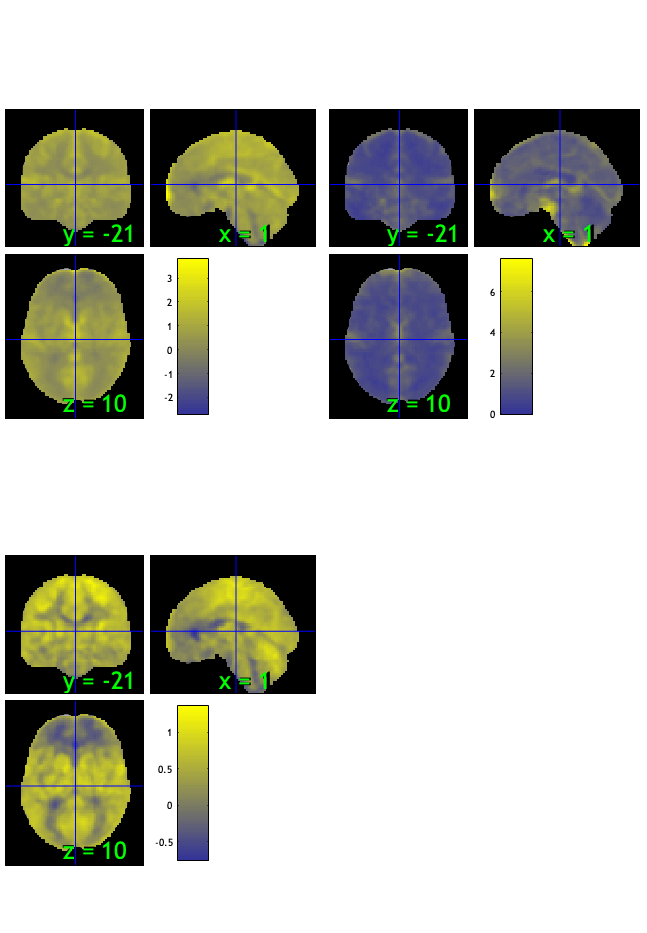

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 4 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 29.27%
Expected 4.10 outside 95% ellipsoid, found   9

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 3 images		Cases 52 63 70 
Uncorrected: 9 images		Cases 1 17 18 19 35 45 52 63 70 

Retained 9 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 51.22%
Expected 4.10 outside 95% ellipsoid, found   2

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 2 images		Cases 32 74 

Mahalanobis (cov and corr, q<0.05 corrected):
  3 images 
                               Outlier_count    Percentage
                        

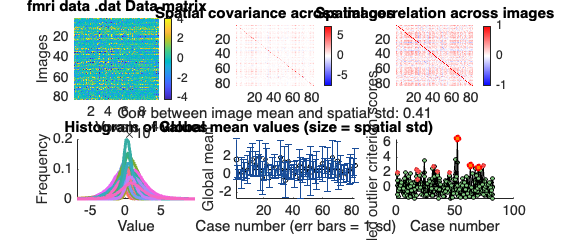

SPM12: spm_check_registration (v7759)              12:29:05 - 24/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
 (all)  

drawnow; snapnow

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj);

#### Pain only :: run robfit

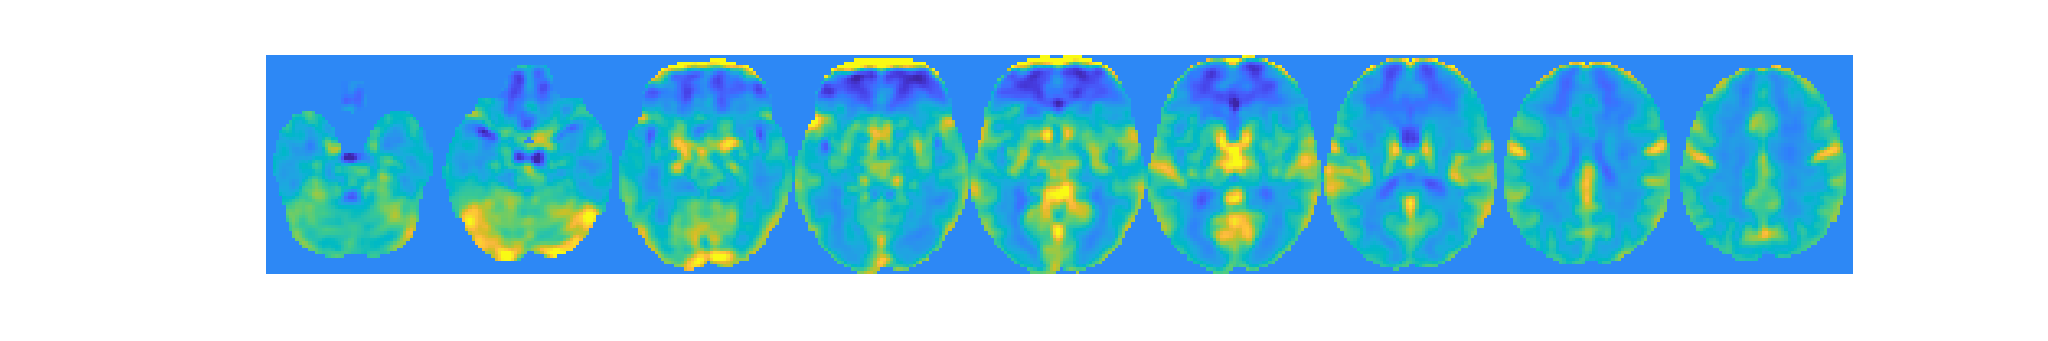

set(gcf,'Visible','on');

figure ('Visible', 'on');
drawnow, snapnow;


#### Pain only :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))));

current length is 82


%for s = 1:length(wh_outlier_corr)
    %disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:);
con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:);
con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:);
%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))));

after removing 3 participants, size is now 79


[path,n,e] = fileparts(con_fldr(wh_outlier_corr));
disp(strcat("participants that are outliers:... ", n));

    "participants that are outliers:... sub-0093"    "participants that are outliers:... sub-0106"    "participants that are outliers:... sub-0118"



disp(n);

    {'sub-0093'}    {'sub-0106'}    {'sub-0118'}



#### Pain only :: plot diagnostics, after l2norm

imgs2 = con.rescale('l2norm_images');

#### Pain only :: ttest

t = ttest(imgs2);

One-sample t-test
Calculating t-statistics and p-values


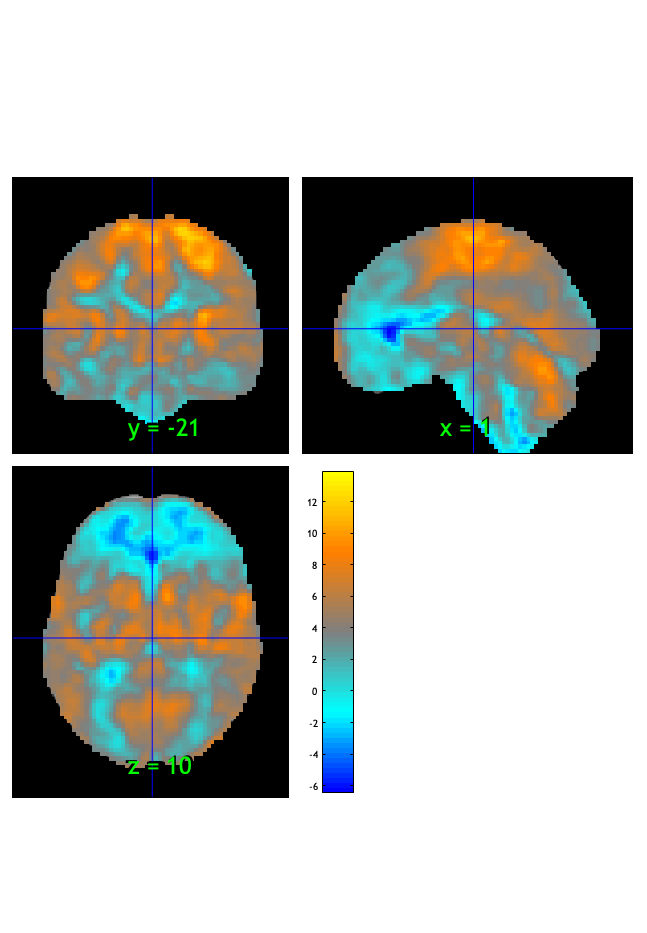

SPM12: spm_check_registration (v7759)              12:29:09 - 24/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


orthviews(t);

drawnow, snapnow;

fdr_t05 = threshold(t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.038126

Image   1
 18 contig. clusters, sizes   1 to 76015
Positive effect: 74395 voxels, min p-value: 0.00000000
Negative effect: 1741 voxels, min p-value: 0.00000000


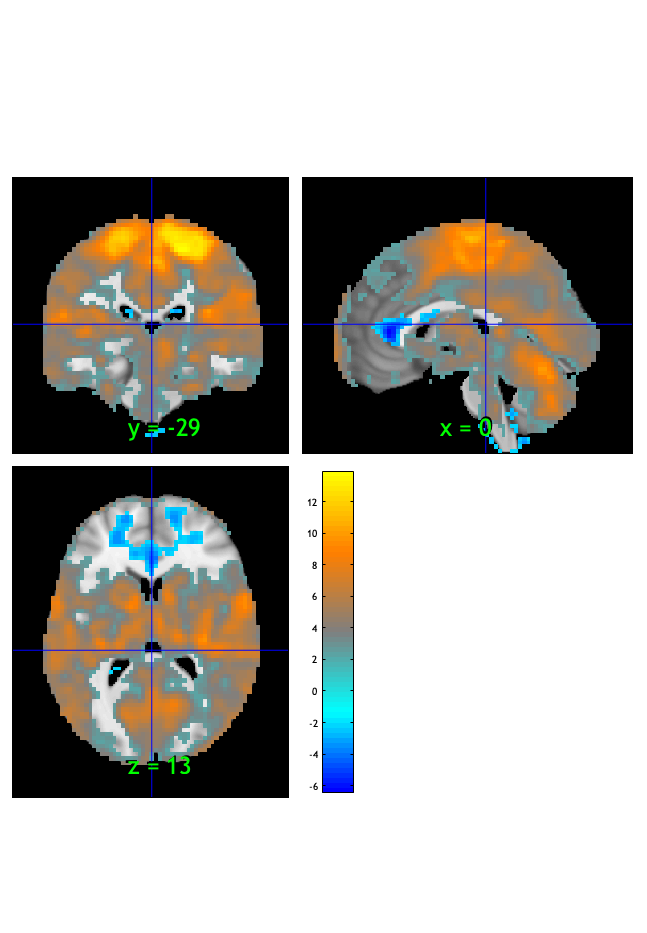

SPM12: spm_check_registration (v7759)              12:29:10 - 24/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


orthviews(fdr_t05);

drawnow, snapnow;
fdr_t05.dat = fdr_t05.dat.*fdr_t05.sig

fdr_t05 =   statistic_image with properties:

              type: 'T'
                 p: [99837×1 single]
            p_type: '2-tailed P-value from input dfe'
               ste: [99837×1 single]
         threshold: 0.0381
          thr_type: []
               sig: [99837×1 logical]
                 N: [99837×1 single]
               dfe: 78
      image_labels: {}
               dat: [99837×1 single]
       dat_descrip: []
           volInfo: [1×1 struct]
    removed_voxels: [99837×1 logical]
    removed_images: 0
       image_names: []
          fullpath: ''
       files_exist: 0
           history: {'Checked image files exist. All exist =   0'  'removed   0 empty voxels and   0 empty images'}


write(fdr_t05, 'fname', fullfile(nifti_save_dir, strcat(nifti_save_fname_prefix, contrast_of_interest, '_fdr-05.nii')), 'overwrite');

Writing: 
/Users/h/Documents/projects_local/cue_expectancy/analysis/fmri/spm/univariate/model01_6cond_ttl/2ndlevel/ttl1_6cond_stimlinear_dummy_P_simple_stimlin_high_gt_low_fdr-05.nii



fdr_t001 = threshold(t, .001, 'fdr');

Image   1 FDR q < 0.001 threshold is 0.000509

Image   1
 37 contig. clusters, sizes   1 to 50469
Positive effect: 50645 voxels, min p-value: 0.00000000
Negative effect: 185 voxels, min p-value: 0.00000000


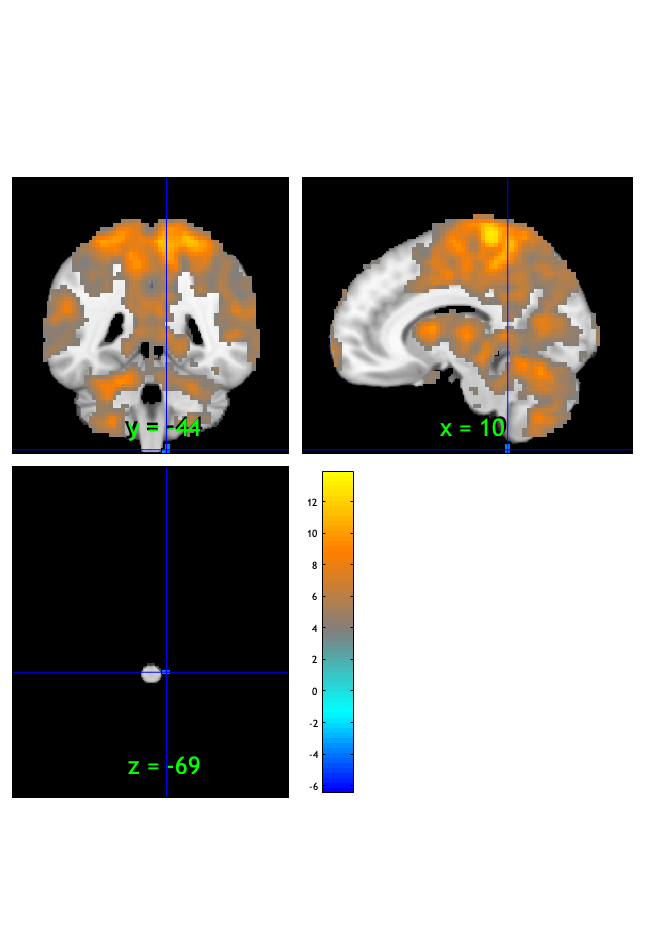

SPM12: spm_check_registration (v7759)              12:29:11 - 24/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


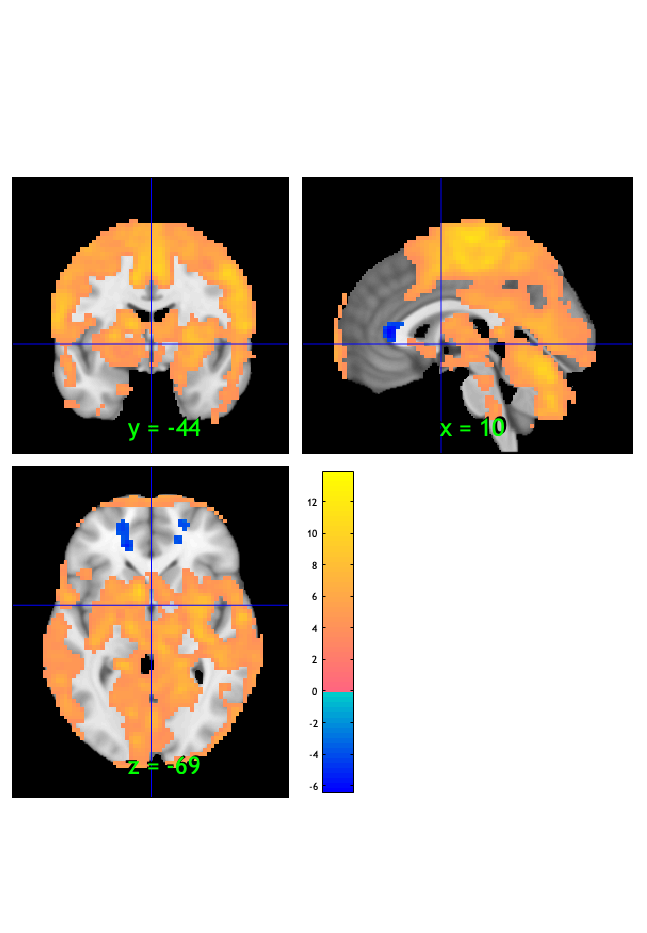

orthviews(fdr_t001);

drawnow, snapnow;
fdr_t001.dat = fdr_t001.dat.*fdr_t001.sig

fdr_t001 =   statistic_image with properties:

              type: 'T'
                 p: [99837×1 single]
            p_type: '2-tailed P-value from input dfe'
               ste: [99837×1 single]
         threshold: 5.0902e-04
          thr_type: []
               sig: [99837×1 logical]
                 N: [99837×1 single]
               dfe: 78
      image_labels: {}
               dat: [99837×1 single]
       dat_descrip: []
           volInfo: [1×1 struct]
    removed_voxels: [99837×1 logical]
    removed_images: 0
       image_names: []
          fullpath: ''
       files_exist: 0
           history: {'Checked image files exist. All exist =   0'  'removed   0 empty voxels and   0 empty images'}


write(fdr_t001, 'fname', fullfile(nifti_save_dir, strcat(nifti_save_fname_prefix, contrast_of_interest, '_fdr-001.nii')), 'overwrite');

Writing: 
/Users/h/Documents/projects_local/cue_expectancy/analysis/fmri/spm/univariate/model01_6cond_ttl/2ndlevel/ttl1_6cond_stimlinear_dummy_P_simple_stimlin_high_gt_low_fdr-001.nii


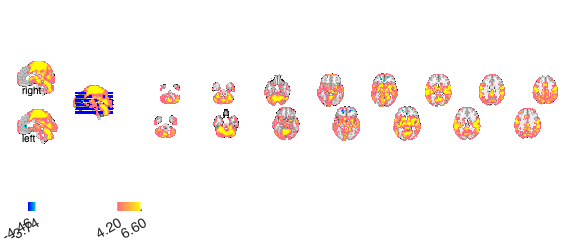

Setting up fmridisplay objects
sagittal montage: 1330 voxels displayed, 49500 not displayed on these slices
sagittal montage: 1360 voxels displayed, 49470 not displayed on these slices
sagittal montage: 1220 voxels displayed, 49610 not displayed on these slices
axial montage: 8707 voxels displayed, 42123 not displayed on these slices
axial montage: 9428 voxels displayed, 41402 not displayed on these slices



create_figure('montage'); axis off;
montage(fdr_t001);

drawnow, snapnow;

#### Pain only :: Neurosynth similarity

[image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( mean(imgs2), 'images_are_replicates', false, 'noverbose');

Input image 1
fullpath_was_empty
_____________________________________________________________________
    testr_low      words_low       testr_high       words_high    
    _________    ______________    __________    _________________

    -0.14035     {'trait'     }     0.25428      {'motor'        }
    -0.13912     {'depression'}      0.2493      {'movements'    }
    -0.13912     {'disorder'  }       0.225      {'sensorimotor' }
    -0.13899     {'judgment'  }     0.20722      {'finger'       }
    -0.13814     {'affect'    }     0.20564      {'hand'         }
    -0.13107     {'face'      }     0.18631      {'somatosensory'}
    -0.12674     {'faces'     }     0.18519      {'muscle'       }
    -0.12648     {'affective' }      0.1831      {'execution'    }
    -0.12602     {'work'      }     0.18167      {'sensory'      }
    -0.12529     {'soci

% [image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( m, 'images_are_replicates', false, 'noverbose');

**Pain only :: Pattern Phil**

[obj, names] = load_image_set('pain_cog_emo');

Loaded images:
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pMCC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_aMCC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pACC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_sgACC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_vmPFC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_dMFC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_MFC_Pain.nii
/Users/h/Documents/MATLAB

bpls_wholebrain = get_wh_image(obj, [8 16 24]);
names_wholebrain = names([8 16 24]);
create_figure('Kragel Pain-Cog-Emo maps', 1, 3);

stats = image_similarity_plot(con_data_obj, 'average', 'mapset', bpls_wholebrain, 'networknames', names_wholebrain, 'nofigure');

Table of correlations Group:1
--------------------------------------
T-test on Fisher's r to Z transformed point-biserial correlations
 	R_avg	T	P	sig	
Pain Wholebrain	0.0041	0.6995	0.4862	0.0000	
Cog Wholebrain	0.0118	3.1482	0.0023	1.0000	
Emo Wholebrain	-0.0145	-2.7458	0.0074	1.0000	
 


axis image

subplot(1, 3, 2)

barplot_columns(stats.r', 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P        Cohens_d
    ___________________    __________    _________    _______    _________    ________

    {'Pain Wholebrain'}    0.0041091     0.0059246    0.69357      0.48994    0.076592
    {'Cog Wholebrain' }     0.011818      0.003754     3.1481    0.0023011     0.34765
    {'Emo Wholebrain' }    -0.014474     0.0052736    -2.7446    0.0074599    -0.30309



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {82×3 cell}
        text_han: {82×3 cell}
       point_han: {82×3 cell}
    star_handles: [16.0005 17.0005 18.0005]


set(gca, 'FontSize', 14)
ylabel('Pattern similarity (r)');
title('Similarity (r) with patterns')

test_data_obj = resample_space(con_data_obj, bpls_wholebrain);

clear csim
for i = 1:3

    csim(:, i) = canlab_pattern_similarity(test_data_obj.dat, bpls_wholebrain.dat(:, i), 'cosine_similarity');

end

Number of zero or NaN values within weight mask, by input image:
 83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83 
Number of zero or NaN values within weight mask, by input image:
 83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83


subplot(1, 3, 3)

barplot_columns(csim, 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P        Cohens_d
    ___________________    __________    _________    _______    _________    ________

    {'Pain Wholebrain'}    0.0074956     0.0056994     1.3152      0.19217     0.14523
    {'Cog Wholebrain' }     0.011004     0.0034697     3.1715    0.0021426     0.35023
    {'Emo Wholebrain' }    -0.017319     0.0051091    -3.3899    0.0010827    -0.37435



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {82×3 cell}
        text_han: {82×3 cell}
       point_han: {82×3 cell}
    star_handles: [19.0005 20.0005 21.0005]


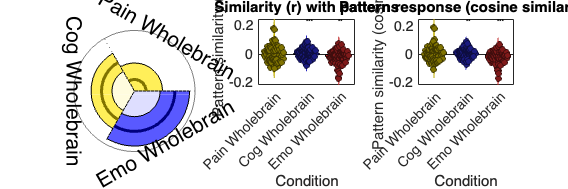

set(gca, 'FontSize', 14)
ylabel('Pattern similarity (cosine sim)');
title('Pattern response (cosine similarity)')

# Vicarious only dummy maps 

# Linear effects of stimlus intensity (low < med < high)

clear all;
close all;

#### Vicarious only :: load dataset


nifti_save_dir = '/Users/h/Documents/projects_local/cue_expectancy/analysis/fmri/spm/univariate/model01_6cond_ttl/2ndlevel';
nifti_save_fname_prefix = 'ttl1_6cond_stimlinear_dummy_';

if ~exist(nifti_save_dir, 'dir')
    mkdir(nifti_save_dir);
end

contrast_of_interest = 'V_simple_stimlin_high_gt_low'

contrast_of_interest = 'V_simple_stimlin_high_gt_low'



mount_dir = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model01_6cond_ttl1/1stlevel';
contrast_name = {'P_VC_cue_high_gt_low', 'V_PC_cue_high_gt_low', 'C_PV_cue_high_gt_low', ...
'P_VC_stimlin_high_gt_low', 'V_PC_stimlin_high_gt_low', 'C_PV_stimlin_high_gt_low',...
'P_VC_stimquad_med_gt_other', 'V_PC_stimquad_med_gt_other', 'C_PV_stimquad_med_gt_other',...
'P_VC_cue_int_stimlin','V_PC_cue_int_stimlin', 'C_PV_cue_int_stimlin',...
'P_VC_cue_int_stimquad','V_PC_cue_int_stimquad','C_PV_cue_int_stimquad',...
'motor',...
'P_simple_cue_high_gt_low', 'V_simple_cue_high_gt_low', 'C_simple_cue_high_gt_low', ...
'P_simple_stimlin_high_gt_low', 'V_simple_stimlin_high_gt_low', 'C_simple_stimlin_high_gt_low',...
'P_simple_stimquad_med_gt_other', 'V_simple_stimquad_med_gt_other', 'C_simple_stimquad_med_gt_other',...
'P_simple_cue_int_stimlin', 'V_simple_cue_int_stimlin', 'C_simple_cue_int_stimlin',...
'P_simple_cue_int_stimquad','V_simple_cue_int_stimquad','C_simple_cue_int_stimquad'
};
index = find(strcmp(contrast_name, contrast_of_interest));
con_name = sprintf('*con_%04d.nii', index);
con_list = dir(fullfile(mount_dir, '*', con_name));
spm('Defaults','fMRI'); 
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';

con_data_obj = fmri_data(con_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
Direct calls to spm_defauts are deprecated.
Please use spm('Defaults',modality) or spm_get_defaults instead.
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 32746536 bytes
Loading image number:    82
Elapsed time is 15.014189 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 7827346  Bit rate: 22.90 bits


#### Vicarious only :: `check data coverage`

m = mean(con_data_obj);
m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans') % display

SPM12: spm_check_registration (v7759)              12:30:14 - 24/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
Grouping contiguous voxels:   1 regions


ans = 1×1 cell array
    {1×1 region}


#### Vicarious only :: Plot diagnostics, before l2norm

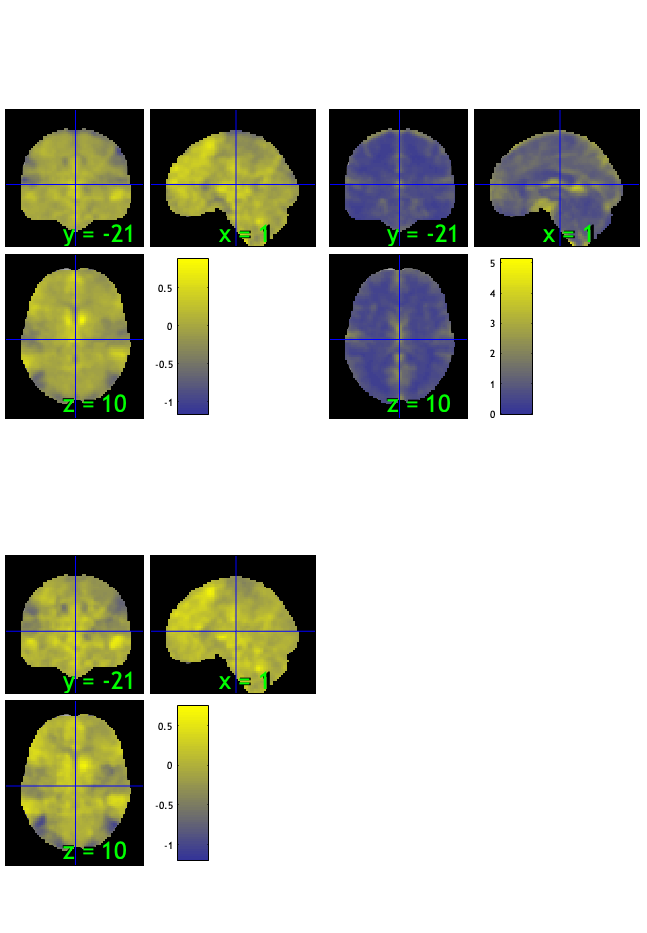

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 3 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 23.17%
Expected 4.10 outside 95% ellipsoid, found   6

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 3 images		Cases 46 67 74 
Uncorrected: 6 images		Cases 7 46 47 56 67 74 

Retained 9 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 48.78%
Expected 4.10 outside 95% ellipsoid, found   1

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 1 images		Cases 47 

Mahalanobis (cov and corr, q<0.05 corrected):
  3 images 
                               Outlier_count    Percentage
                               

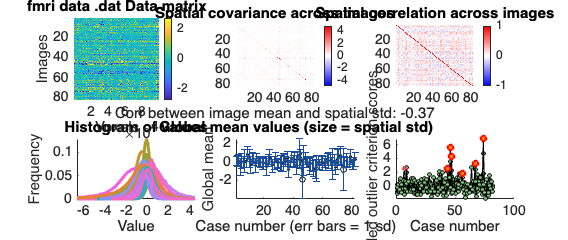

SPM12: spm_check_registration (v7759)              12:30:46 - 24/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
 (all)  

drawnow; snapnow;

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj);

#### Vicarious only :: run robfit

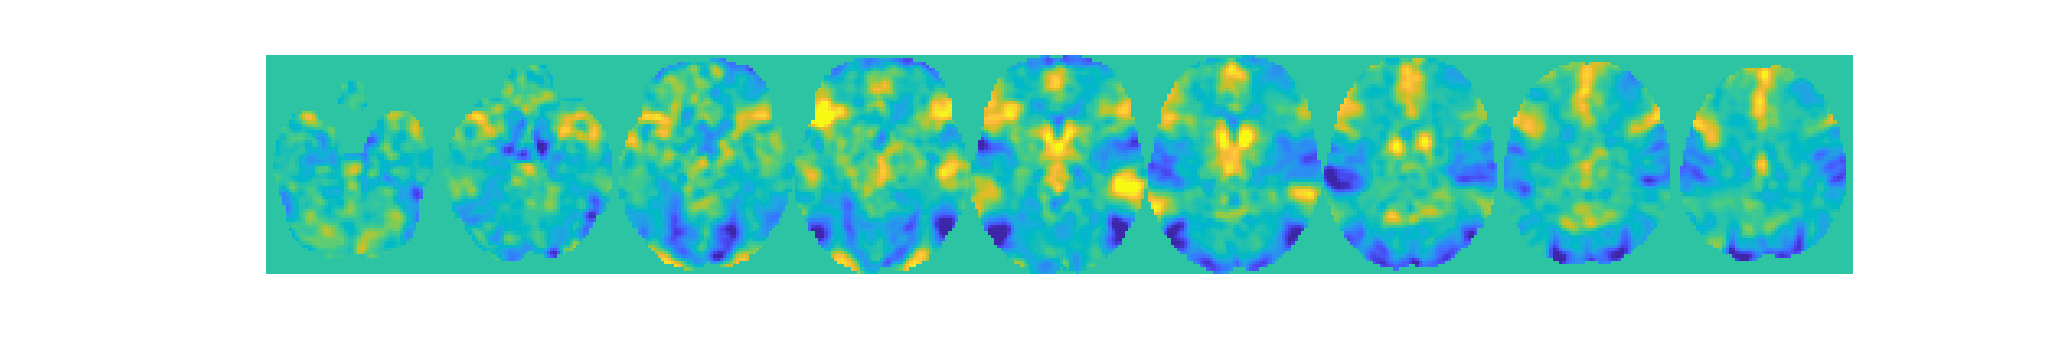

set(gcf,'Visible','on');

figure ('Visible', 'on');
drawnow, snapnow;

#### Vicarious only :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))));

current length is 82


%for s = 1:length(wh_outlier_corr)
  %  disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:);
con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:);
con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:);
%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))));

after removing 6 participants, size is now 76


[path,n,e] = fileparts(con_fldr(wh_outlier_corr));
disp(strcat("participants that are outliers:... ", n));

    "participants that are out…"    "participants that are out…"    "participants that are out…"    "participants that are out…"    "participants that are out…"    "participants that are out…"



disp(n);

    {'sub-0082'}    {'sub-0085'}    {'sub-0086'}    {'sub-0098'}    {'sub-0114'}    {'sub-0123'}



#### Vicarious only :: plot diagnostics, after l2norm

imgs2 = con.rescale('l2norm_images');

#### Vicarious only :: ttest

t = ttest(imgs2);

One-sample t-test
Calculating t-statistics and p-values


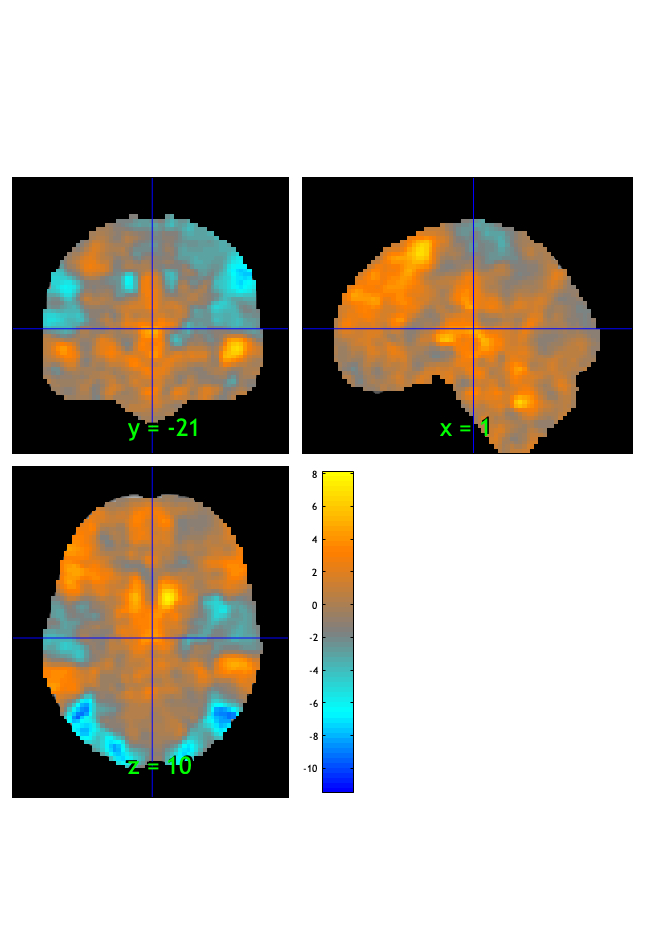

SPM12: spm_check_registration (v7759)              12:30:49 - 24/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


orthviews(t);

drawnow, snapnow;

fdr_t05 = threshold(t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.010537

Image   1
 82 contig. clusters, sizes   1 to 7699
Positive effect: 8235 voxels, min p-value: 0.00000000
Negative effect: 12804 voxels, min p-value: 0.00000000


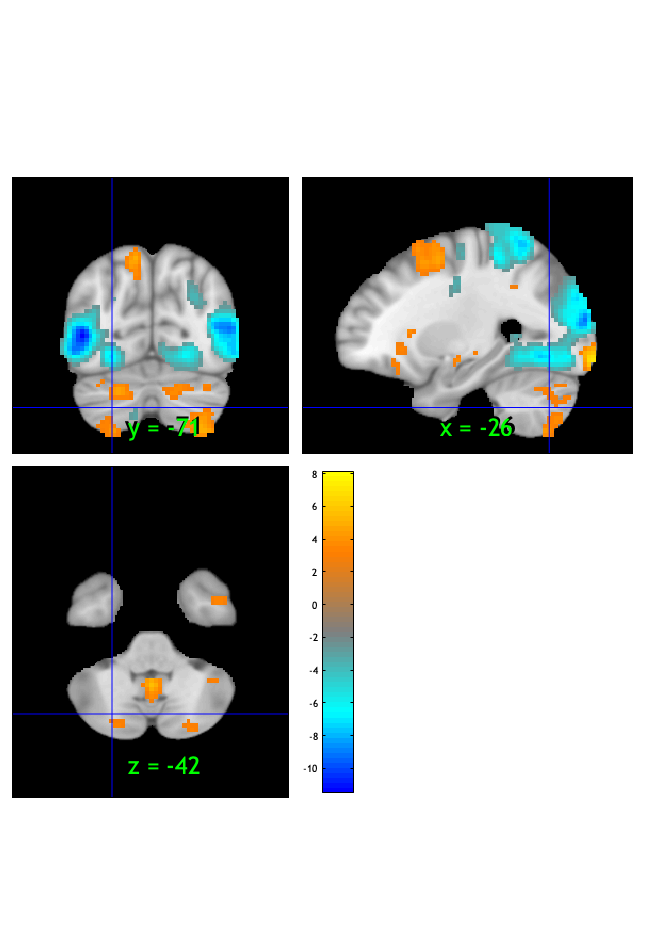

SPM12: spm_check_registration (v7759)              12:30:51 - 24/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


orthviews(fdr_t05);

drawnow, snapnow;
fdr_t05.dat = fdr_t05.dat.*fdr_t05.sig

fdr_t05 =   statistic_image with properties:

              type: 'T'
                 p: [99837×1 single]
            p_type: '2-tailed P-value from input dfe'
               ste: [99837×1 single]
         threshold: 0.0105
          thr_type: []
               sig: [99837×1 logical]
                 N: [99837×1 single]
               dfe: 75
      image_labels: {}
               dat: [99837×1 single]
       dat_descrip: []
           volInfo: [1×1 struct]
    removed_voxels: [99837×1 logical]
    removed_images: 0
       image_names: []
          fullpath: ''
       files_exist: 0
           history: {'Checked image files exist. All exist =   0'  'removed   0 empty voxels and   0 empty images'}


write(fdr_t05, 'fname', fullfile(nifti_save_dir, strcat(nifti_save_fname_prefix, contrast_of_interest, '_fdr-05.nii')), 'overwrite');

Writing: 
/Users/h/Documents/projects_local/cue_expectancy/analysis/fmri/spm/univariate/model01_6cond_ttl/2ndlevel/ttl1_6cond_stimlinear_dummy_V_simple_stimlin_high_gt_low_fdr-05.nii



fdr_t001 = threshold(t, .001, 'fdr');

Image   1 FDR q < 0.001 threshold is 0.000069

Image   1
 42 contig. clusters, sizes   1 to 1263
Positive effect: 1784 voxels, min p-value: 0.00000000
Negative effect: 5126 voxels, min p-value: 0.00000000


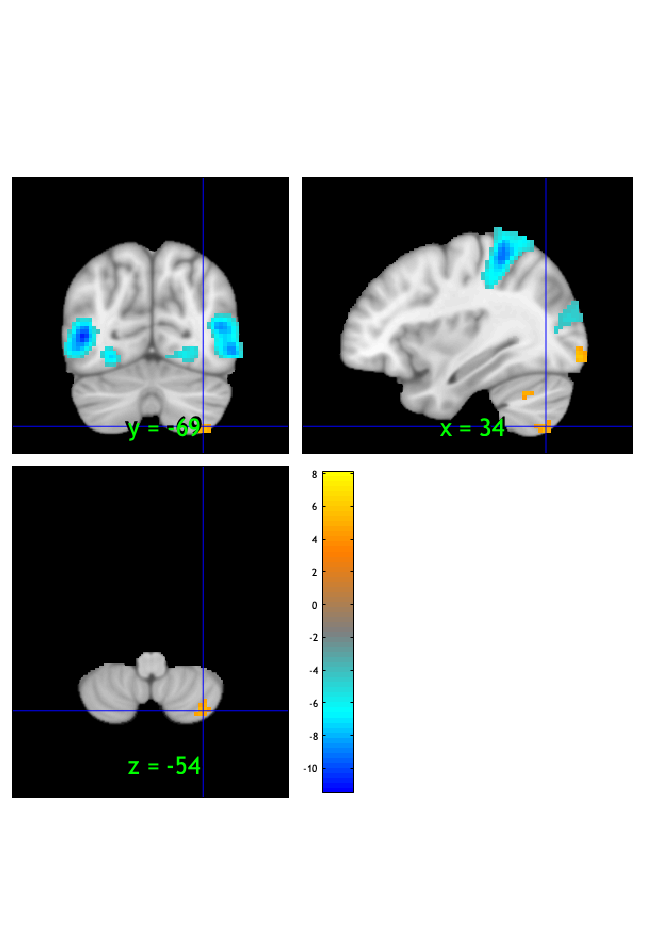

SPM12: spm_check_registration (v7759)              12:30:52 - 24/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


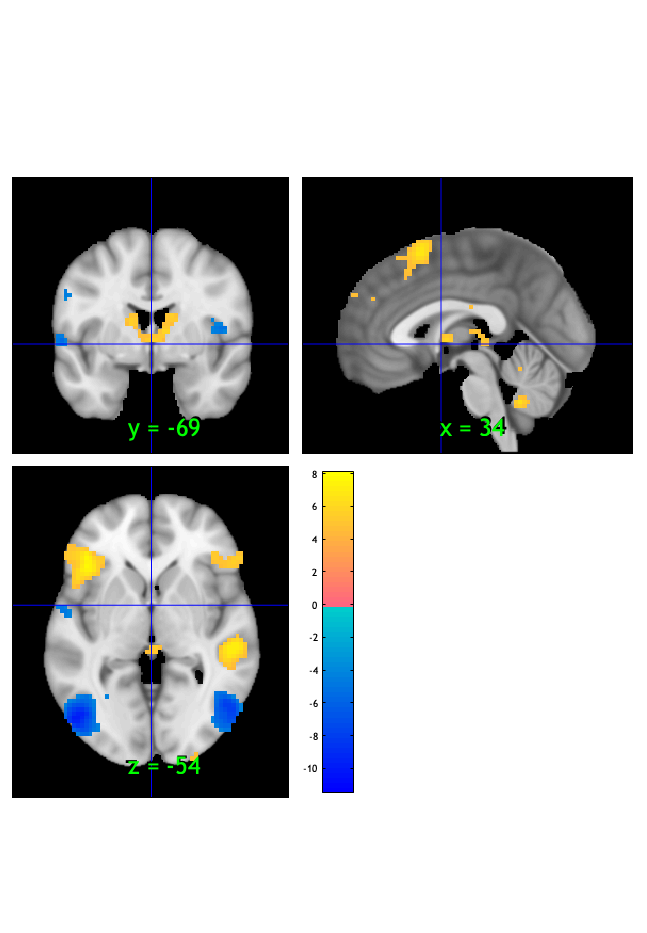

orthviews(fdr_t001);

drawnow, snapnow;
fdr_t001.dat = fdr_t001.dat.*fdr_t001.sig

fdr_t001 =   statistic_image with properties:

              type: 'T'
                 p: [99837×1 single]
            p_type: '2-tailed P-value from input dfe'
               ste: [99837×1 single]
         threshold: 6.9141e-05
          thr_type: []
               sig: [99837×1 logical]
                 N: [99837×1 single]
               dfe: 75
      image_labels: {}
               dat: [99837×1 single]
       dat_descrip: []
           volInfo: [1×1 struct]
    removed_voxels: [99837×1 logical]
    removed_images: 0
       image_names: []
          fullpath: ''
       files_exist: 0
           history: {'Checked image files exist. All exist =   0'  'removed   0 empty voxels and   0 empty images'}


write(fdr_t001, 'fname', fullfile(nifti_save_dir, strcat(nifti_save_fname_prefix, contrast_of_interest, '_fdr-001.nii')), 'overwrite');

Writing: 
/Users/h/Documents/projects_local/cue_expectancy/analysis/fmri/spm/univariate/model01_6cond_ttl/2ndlevel/ttl1_6cond_stimlinear_dummy_V_simple_stimlin_high_gt_low_fdr-001.nii


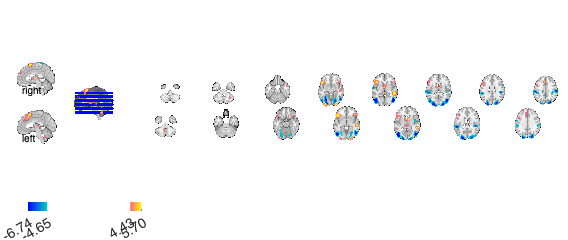

Setting up fmridisplay objects
sagittal montage:  87 voxels displayed, 6823 not displayed on these slices
sagittal montage:  58 voxels displayed, 6852 not displayed on these slices
sagittal montage:  69 voxels displayed, 6841 not displayed on these slices
axial montage: 1191 voxels displayed, 5719 not displayed on these slices
axial montage: 1396 voxels displayed, 5514 not displayed on these slices



create_figure('montage'); axis off;
montage(fdr_t001);

drawnow, snapnow;

#### Vicarious only :: Neurosynth similarity

[image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( mean(imgs2), 'images_are_replicates', false, 'noverbose');

Input image 1
fullpath_was_empty
_____________________________________________________________________
    testr_low      words_low      testr_high     words_high  
    _________    _____________    __________    _____________

      -0.363     {'motion'   }     0.27485      {'verb'     }
    -0.33553     {'visual'   }     0.26767      {'verbal'   }
     -0.3195     {'spatial'  }     0.23099      {'word'     }
    -0.29798     {'hand'     }     0.22033      {'retrieval'}
    -0.29579     {'tactile'  }     0.21144      {'memory'   }
     -0.2808     {'shape'    }     0.21024      {'semantic' }
     -0.2638     {'movements'}     0.20601      {'sentences'}
    -0.25768     {'eye'      }     0.19684      {'reward'   }
    -0.25647     {'object'   }     0.19469      {'language' }
      -0.253     {'position' }     0.18934      {'affect'   }



Vicarious only **:: Pattern Phil**

[obj, names] = load_image_set('pain_cog_emo');

Loaded images:
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pMCC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_aMCC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pACC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_sgACC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_vmPFC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_dMFC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_MFC_Pain.nii
/Users/h/Documents/MATLAB

bpls_wholebrain = get_wh_image(obj, [8 16 24]);
names_wholebrain = names([8 16 24]);
create_figure('Kragel Pain-Cog-Emo maps', 1, 3);

stats = image_similarity_plot(con_data_obj, 'average', 'mapset', bpls_wholebrain, 'networknames', names_wholebrain, 'nofigure');

Table of correlations Group:1
--------------------------------------
T-test on Fisher's r to Z transformed point-biserial correlations
 	R_avg	T	P	sig	
Pain Wholebrain	-0.0087	-1.4055	0.1637	0.0000	
Cog Wholebrain	-0.0029	-0.7534	0.4534	0.0000	
Emo Wholebrain	0.0108	1.6418	0.1045	0.0000	
 


axis image

subplot(1, 3, 2)

barplot_columns(stats.r', 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P       Cohens_d 
    ___________________    __________    _________    ________    _______    _________

    {'Pain Wholebrain'}    -0.0086758    0.0061716     -1.4058    0.16362     -0.15524
    {'Cog Wholebrain' }    -0.0029383     0.003903    -0.75284    0.45373    -0.083137
    {'Emo Wholebrain' }      0.010843    0.0066041      1.6419    0.10449      0.18132



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {82×3 cell}
        text_han: {82×3 cell}
       point_han: {82×3 cell}
    star_handles: [14.0006 15.0006 16.0006]


set(gca, 'FontSize', 14)
ylabel('Pattern similarity (r)');
title('Similarity (r) with patterns')

test_data_obj = resample_space(con_data_obj, bpls_wholebrain);

clear csim
for i = 1:3

    csim(:, i) = canlab_pattern_similarity(test_data_obj.dat, bpls_wholebrain.dat(:, i), 'cosine_similarity');

end

Number of zero or NaN values within weight mask, by input image:
 83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83 
Number of zero or NaN values within weight mask, by input image:
 83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83


subplot(1, 3, 3)

barplot_columns(csim, 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P        Cohens_d 
    ___________________    __________    _________    ________    ________    _________

    {'Pain Wholebrain'}     -0.008612     0.006035      -1.427     0.15742     -0.15759
    {'Cog Wholebrain' }    -0.0028725    0.0036104    -0.79563     0.42857    -0.087862
    {'Emo Wholebrain' }      0.010898      0.00646      1.6869    0.095465      0.18629



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {82×3 cell}
        text_han: {82×3 cell}
       point_han: {82×3 cell}
    star_handles: [17.0006 18.0006 19.0006]


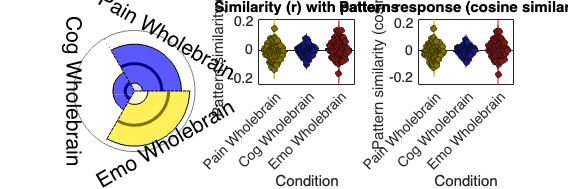

set(gca, 'FontSize', 14)
ylabel('Pattern similarity (cosine sim)');
title('Pattern response (cosine similarity)')

# Cognitive only dummy maps 

# Linear effects of stimlus intensity (low < med < high)

#### Cognitive only :: load dataset

clear all; close all;

nifti_save_dir = '/Users/h/Documents/projects_local/cue_expectancy/analysis/fmri/spm/univariate/model01_6cond_ttl/2ndlevel';
nifti_save_fname_prefix = 'ttl1_6cond_stimlinear_dummy_';

if ~exist(nifti_save_dir, 'dir')
    mkdir(nifti_save_dir);
end
contrast_of_interest = 'C_simple_stimlin_high_gt_low';

mount_dir = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model01_6cond_ttl1/1stlevel';
contrast_name = {'P_VC_cue_high_gt_low', 'V_PC_cue_high_gt_low', 'C_PV_cue_high_gt_low', ...
'P_VC_stimlin_high_gt_low', 'V_PC_stimlin_high_gt_low', 'C_PV_stimlin_high_gt_low',...
'P_VC_stimquad_med_gt_other', 'V_PC_stimquad_med_gt_other', 'C_PV_stimquad_med_gt_other',...
'P_VC_cue_int_stimlin','V_PC_cue_int_stimlin', 'C_PV_cue_int_stimlin',...
'P_VC_cue_int_stimquad','V_PC_cue_int_stimquad','C_PV_cue_int_stimquad',...
'motor',...
'P_simple_cue_high_gt_low', 'V_simple_cue_high_gt_low', 'C_simple_cue_high_gt_low', ...
'P_simple_stimlin_high_gt_low', 'V_simple_stimlin_high_gt_low', 'C_simple_stimlin_high_gt_low',...
'P_simple_stimquad_m`ed_gt_other', 'V_simple_stimquad_med_gt_other', 'C_simple_stimquad_med_gt_other',...
'P_simple_cue_int_stimlin', 'V_simple_cue_int_stimlin', 'C_simple_cue_int_stimlin',...
'P_simple_cue_int_stimquad','V_simple_cue_int_stimquad','C_simple_cue_int_stimquad'
};

index = find(strcmp(contrast_name, contrast_of_interest));
con_name = sprintf('*con_%04d.nii', index);
con_list = dir(fullfile(mount_dir, '*', con_name));
spm('Defaults','fMRI') 
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
Direct calls to spm_defauts are deprecated.
Please use spm('Defaults',modality) or spm_get_defaults instead.
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 32746536 bytes
Loading image number:    82
Elapsed time is 22.613146 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 7823231  Bit rate: 22.90 bits


#### Cognitive only :: `check data coverage`

m = mean(con_data_obj);
% m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans'); % display

SPM12: spm_check_registration (v7759)              12:32:07 - 24/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
Grouping contiguous voxels:   1 regions


#### Cognitive only :: Plot diagnostics, before l2norm

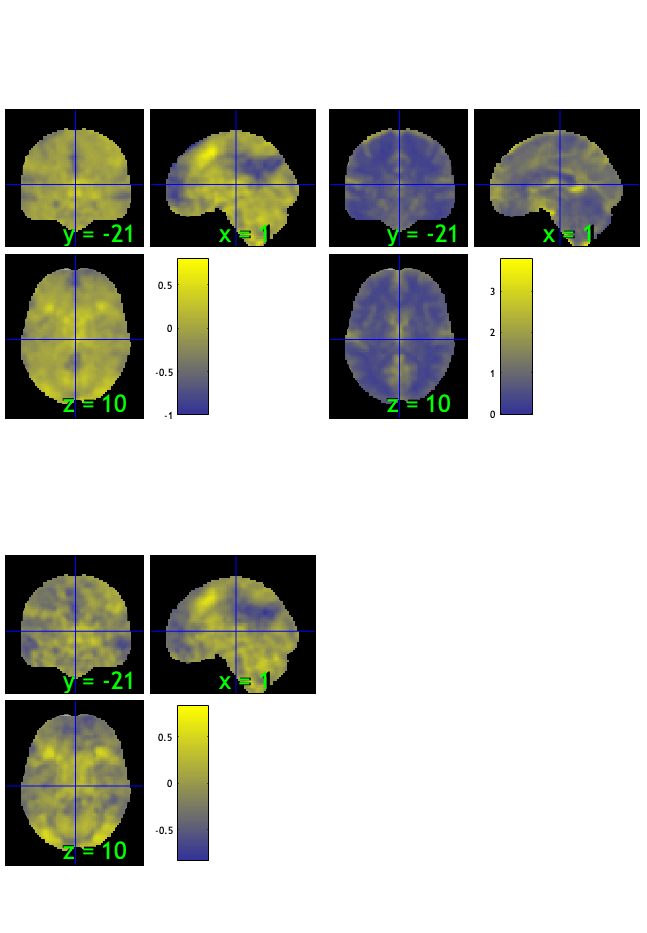

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 3 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 21.95%
Expected 4.10 outside 95% ellipsoid, found   4

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 3 images		Cases 44 72 74 
Uncorrected: 4 images		Cases 44 46 72 74 

Retained 11 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 47.56%
Expected 4.10 outside 95% ellipsoid, found   0

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 0 images		Cases  

Mahalanobis (cov and corr, q<0.05 corrected):
  3 images 
                               Outlier_count    Percentage
                               ___

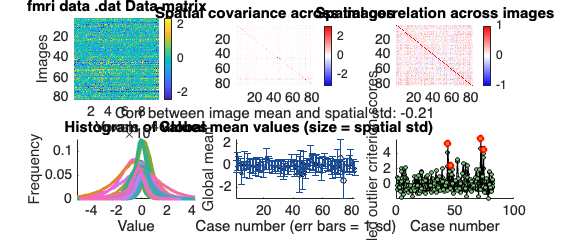

SPM12: spm_check_registration (v7759)              12:32:40 - 24/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
 (all)  

drawnow; snapnow;

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj);

#### Cognitive only :: run robfit

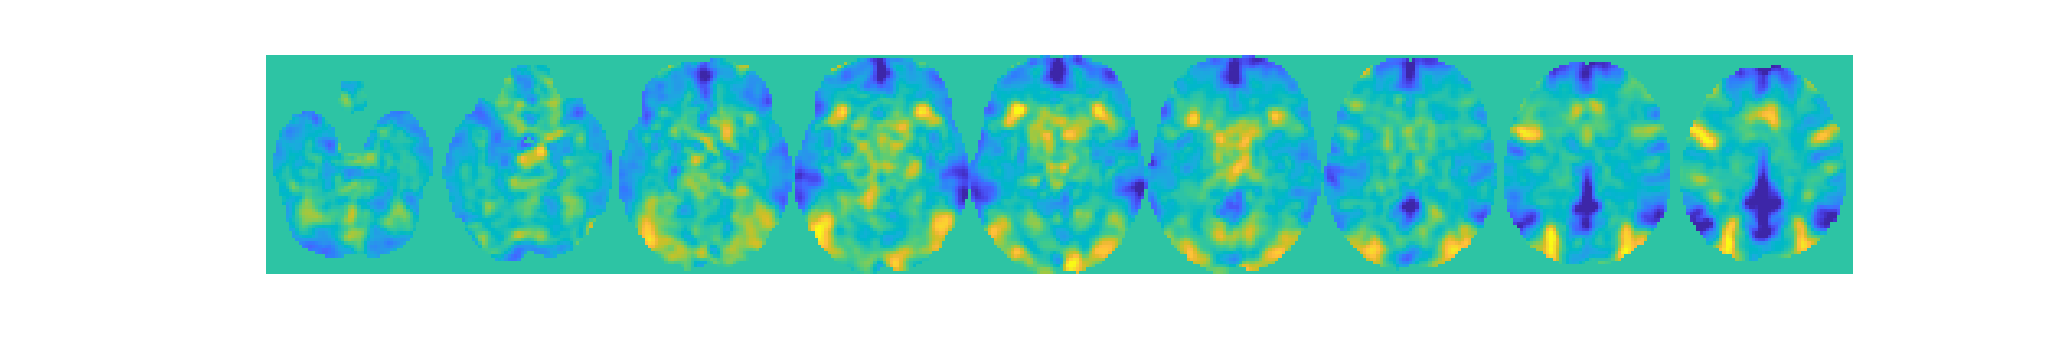

set(gcf,'Visible','on');

figure ('Visible', 'on');
drawnow, snapnow;

#### Cognitive only :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))));

current length is 82


%for s = 1:length(wh_outlier_corr)
   % disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:);
con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:);
con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:);
%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))));

after removing 4 participants, size is now 78


[path,n,e] = fileparts(con_fldr(wh_outlier_corr));
disp(strcat("participants that are outliers:... ", n));

    "participants that are outliers:... sub-00…"    "participants that are outliers:... sub-00…"    "participants that are outliers:... sub-01…"    "participants that are outliers:... sub-01…"



disp(n);

    {'sub-0082'}    {'sub-0085'}    {'sub-0120'}    {'sub-0123'}



#### Cognitive only:: plot diagnostics, after l2norm

imgs2 = con.rescale('l2norm_images');

#### Cognitive only :: ttest

t = ttest(imgs2);

One-sample t-test
Calculating t-statistics and p-values


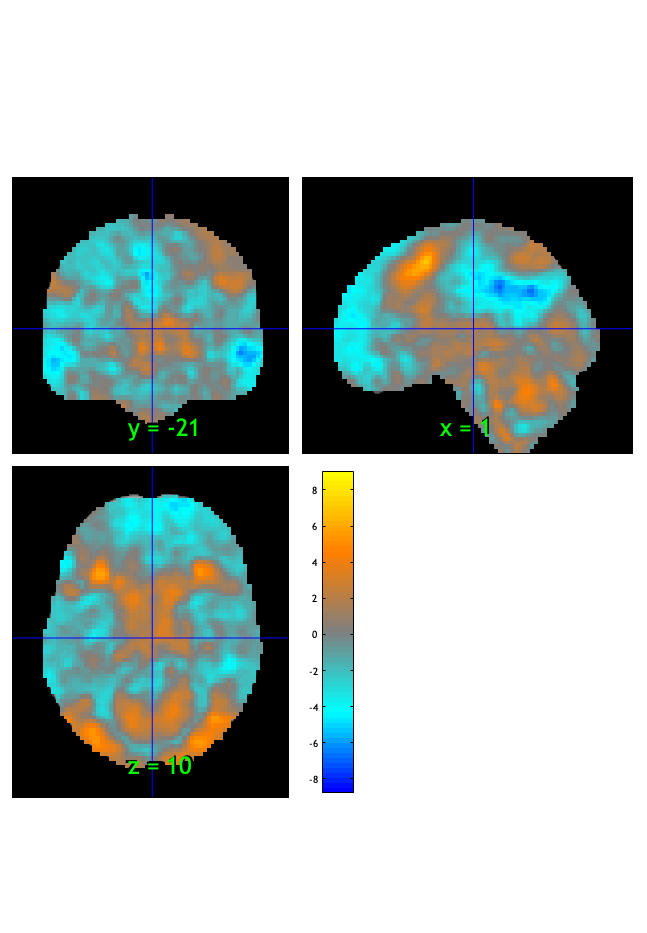

SPM12: spm_check_registration (v7759)              12:32:44 - 24/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


orthviews(t);

drawnow, snapnow;

fdr_t05 = threshold(t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.012914

Image   1
100 contig. clusters, sizes   1 to 19278
Positive effect: 10177 voxels, min p-value: 0.00000000
Negative effect: 15612 voxels, min p-value: 0.00000000


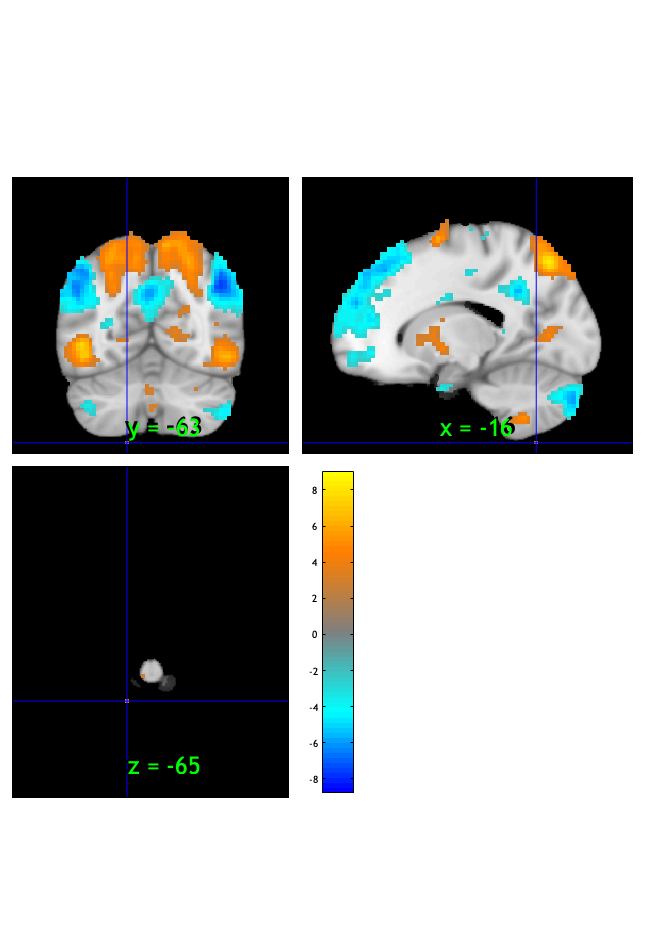

SPM12: spm_check_registration (v7759)              12:32:46 - 24/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


orthviews(fdr_t05);

drawnow, snapnow;
fdr_t05.dat = fdr_t05.dat.*fdr_t05.sig

fdr_t05 =   statistic_image with properties:

              type: 'T'
                 p: [99837×1 single]
            p_type: '2-tailed P-value from input dfe'
               ste: [99837×1 single]
         threshold: 0.0129
          thr_type: []
               sig: [99837×1 logical]
                 N: [99837×1 single]
               dfe: 77
      image_labels: {}
               dat: [99837×1 single]
       dat_descrip: []
           volInfo: [1×1 struct]
    removed_voxels: [99837×1 logical]
    removed_images: 0
       image_names: []
          fullpath: ''
       files_exist: 0
           history: {'Checked image files exist. All exist =   0'  'removed   0 empty voxels and   0 empty images'}


write(fdr_t05, 'fname', fullfile(nifti_save_dir, strcat(nifti_save_fname_prefix, contrast_of_interest, '_fdr-05.nii')), 'overwrite');

Writing: 
/Users/h/Documents/projects_local/cue_expectancy/analysis/fmri/spm/univariate/model01_6cond_ttl/2ndlevel/ttl1_6cond_stimlinear_dummy_C_simple_stimlin_high_gt_low_fdr-05.nii



fdr_t001 = threshold(t, .001, 'fdr');

Image   1 FDR q < 0.001 threshold is 0.000082

Image   1
 54 contig. clusters, sizes   1 to 1166
Positive effect: 3984 voxels, min p-value: 0.00000000
Negative effect: 4163 voxels, min p-value: 0.00000000


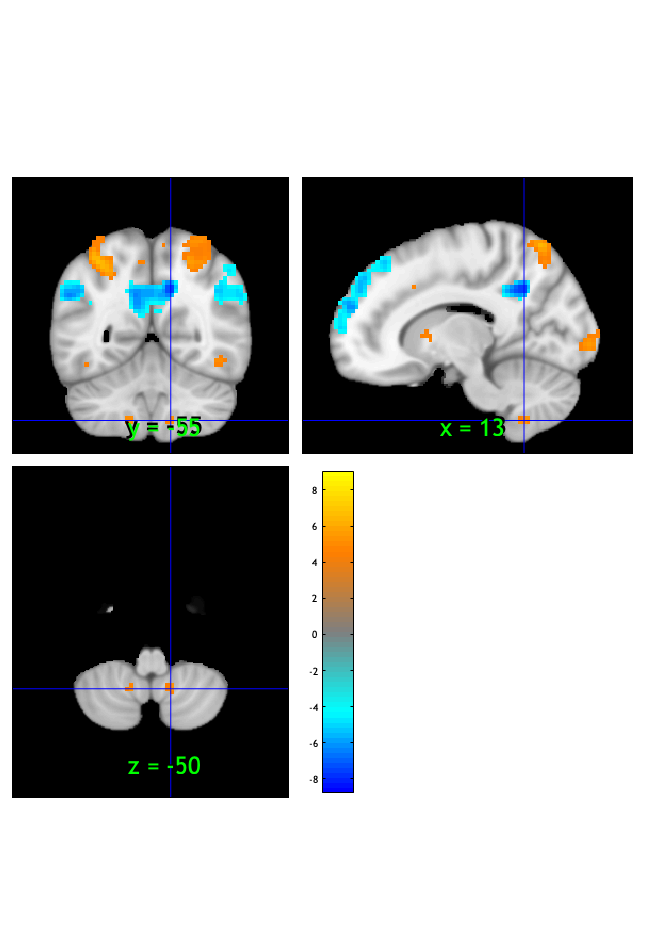

SPM12: spm_check_registration (v7759)              12:32:47 - 24/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


orthviews(fdr_t001);

drawnow, snapnow;
fdr_t001.dat = fdr_t001.dat.*fdr_t001.sig

fdr_t001 =   statistic_image with properties:

              type: 'T'
                 p: [99837×1 single]
            p_type: '2-tailed P-value from input dfe'
               ste: [99837×1 single]
         threshold: 8.1539e-05
          thr_type: []
               sig: [99837×1 logical]
                 N: [99837×1 single]
               dfe: 77
      image_labels: {}
               dat: [99837×1 single]
       dat_descrip: []
           volInfo: [1×1 struct]
    removed_voxels: [99837×1 logical]
    removed_images: 0
       image_names: []
          fullpath: ''
       files_exist: 0
           history: {'Checked image files exist. All exist =   0'  'removed   0 empty voxels and   0 empty images'}


write(fdr_t001, 'fname', fullfile(nifti_save_dir, strcat(nifti_save_fname_prefix, contrast_of_interest, '_fdr-001.nii')), 'overwrite');

Writing: 
/Users/h/Documents/projects_local/cue_expectancy/analysis/fmri/spm/univariate/model01_6cond_ttl/2ndlevel/ttl1_6cond_stimlinear_dummy_C_simple_stimlin_high_gt_low_fdr-001.nii


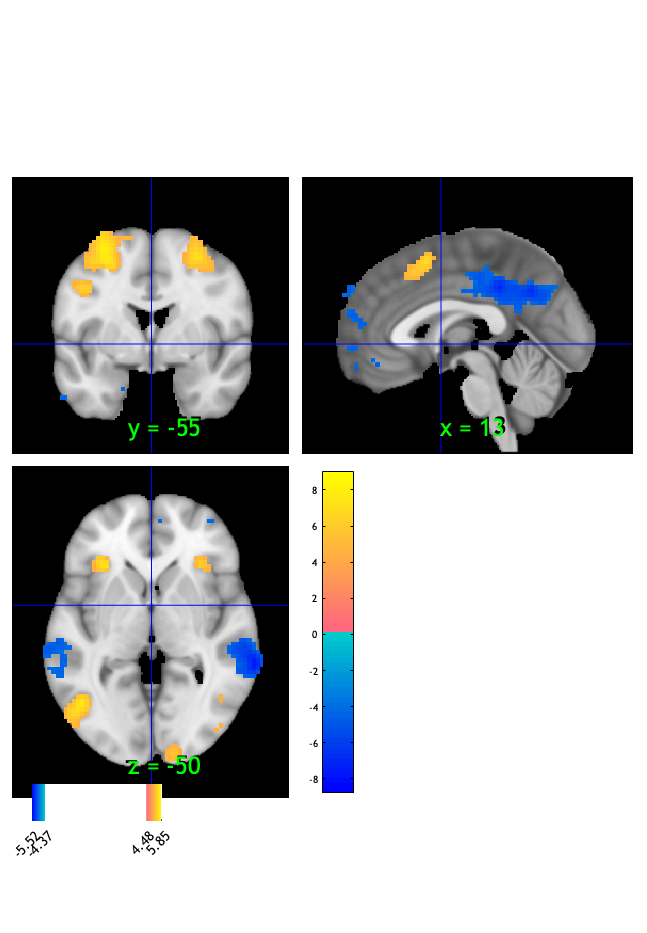

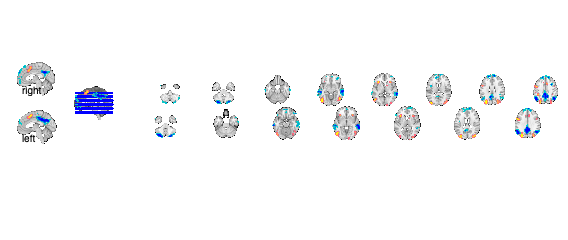

Setting up fmridisplay objects
sagittal montage: 178 voxels displayed, 7969 not displayed on these slices
sagittal montage: 142 voxels displayed, 8005 not displayed on these slices
sagittal montage: 177 voxels displayed, 7970 not displayed on these slices
axial montage: 1490 voxels displayed, 6657 not displayed on these slices
axial montage: 1653 voxels displayed, 6494 not displayed on these slices



create_figure('montage'); axis off;
montage(fdr_t001);

drawnow, snapnow;

#### gnitive only :: Neurosynth similarity

[image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( mean(imgs2), 'images_are_replicates', false, 'noverbose');

Input image 1
fullpath_was_empty
_____________________________________________________________________
    testr_low       words_low        testr_high       words_high   
    _________    ________________    __________    ________________

    -0.32596     {'person'      }     0.37303      {'visual'      }
    -0.31749     {'trait'       }     0.31449      {'eye'         }
    -0.29636     {'social'      }     0.27525      {'maintenance' }
    -0.29087     {'personal'    }     0.27514      {'target'      }
    -0.28888     {'default'     }     0.26771      {'saccade'     }
    -0.28746     {'self'        }     0.26759      {'letter'      }
    -0.27146     {'rating'      }     0.25529      {'visuospatial'}
    -0.27104     {'positive'    }     0.25281      {'spatial'     }
    -0.26306     {'negative'    }     0.24648      {'attention'   }
     -0.2588

Cognitive only **:: Pattern Phil**

[obj, names] = load_image_set('pain_cog_emo');

Loaded images:
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pMCC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_aMCC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pACC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_sgACC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_vmPFC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_dMFC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_MFC_Pain.nii
/Users/h/Documents/MATLAB

bpls_wholebrain = get_wh_image(obj, [8 16 24]);
names_wholebrain = names([8 16 24]);
create_figure('Kragel Pain-Cog-Emo maps', 1, 3);

stats = image_similarity_plot(con_data_obj, 'average', 'mapset', bpls_wholebrain, 'networknames', names_wholebrain, 'nofigure');

Table of correlations Group:1
--------------------------------------
T-test on Fisher's r to Z transformed point-biserial correlations
 	R_avg	T	P	sig	
Pain Wholebrain	-0.0034	-0.6172	0.5388	0.0000	
Cog Wholebrain	-0.0227	-4.6149	0.0000	1.0000	
Emo Wholebrain	0.0236	3.5770	0.0006	1.0000	
 


axis image

subplot(1, 3, 2)

barplot_columns(stats.r', 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T            P         Cohens_d 
    ___________________    __________    _________    ________    __________    _________

    {'Pain Wholebrain'}    -0.003412     0.0055341    -0.61654       0.53927    -0.068086
    {'Cog Wholebrain' }     -0.02274     0.0049256     -4.6167    1.4461e-05     -0.50983
    {'Emo Wholebrain' }     0.023596     0.0065929       3.579      0.000586      0.39524



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {82×3 cell}
        text_han: {82×3 cell}
       point_han: {82×3 cell}
    star_handles: [13.0007 14.0007 15.0007]


set(gca, 'FontSize', 14)
ylabel('Pattern similarity (r)');
title('Similarity (r) with patterns')

test_data_obj = resample_space(con_data_obj, bpls_wholebrain);

clear csim
for i = 1:3

    csim(:, i) = canlab_pattern_similarity(test_data_obj.dat, bpls_wholebrain.dat(:, i), 'cosine_similarity');

end

Number of zero or NaN values within weight mask, by input image:
 83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83 
Number of zero or NaN values within weight mask, by input image:
 83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83


subplot(1, 3, 3)

barplot_columns(csim, 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T            P         Cohens_d 
    ___________________    __________    _________    ________    __________    _________

    {'Pain Wholebrain'}    -0.0033547    0.0054801    -0.61217       0.54214    -0.067602
    {'Cog Wholebrain' }     -0.021921    0.0047794     -4.5866     1.622e-05      -0.5065
    {'Emo Wholebrain' }       0.02341    0.0066205      3.5359    0.00067522      0.39048



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {82×3 cell}
        text_han: {82×3 cell}
       point_han: {82×3 cell}
    star_handles: [16.0007 17.0007 18.0007]


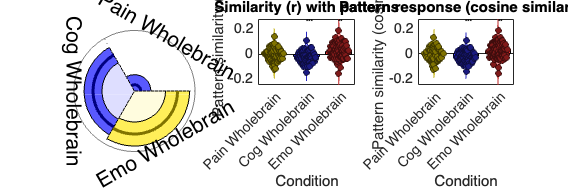

set(gca, 'FontSize', 14)
ylabel('Pattern similarity (cosine sim)');
title('Pattern response (cosine similarity)')

drawnow, snapnow;


# Manipulation check Rating

# motor contrast

#### motor only :: load dataset

clear all; close all;
nifti_save_dir = '/Users/h/Documents/projects_local/cue_expectancy/analysis/fmri/spm/univariate/model01_6cond_ttl/2ndlevel';
nifti_save_fname_prefix = 'ttl1_6cond_stimlinear_dummy_';

if ~exist(nifti_save_dir, 'dir')
    mkdir(nifti_save_dir);
end
contrast_of_interest = 'motor'

contrast_of_interest = 'motor'

mount_dir = '/Volumes/spacetop_projects_cue/analysis/fmri/spm/univariate/model01_6cond_ttl1/1stlevel';
contrast_name = {'P_VC_cue_high_gt_low', 'V_PC_cue_high_gt_low', 'C_PV_cue_high_gt_low', ...
'P_VC_stimlin_high_gt_low', 'V_PC_stimlin_high_gt_low', 'C_PV_stimlin_high_gt_low',...
'P_VC_stimquad_med_gt_other', 'V_PC_stimquad_med_gt_other', 'C_PV_stimquad_med_gt_other',...
'P_VC_cue_int_stimlin','V_PC_cue_int_stimlin', 'C_PV_cue_int_stimlin',...
'P_VC_cue_int_stimquad','V_PC_cue_int_stimquad','C_PV_cue_int_stimquad',...
'motor',...
'P_simple_cue_high_gt_low', 'V_simple_cue_high_gt_low', 'C_simple_cue_high_gt_low', ...
'P_simple_stimlin_high_gt_low', 'V_simple_stimlin_high_gt_low', 'C_simple_stimlin_high_gt_low',...
'P_simple_stimquad_med_gt_other', 'V_simple_stimquad_med_gt_other', 'C_simple_stimquad_med_gt_other',...
'P_simple_cue_int_stimlin', 'V_simple_cue_int_stimlin', 'C_simple_cue_int_stimlin',...
'P_simple_cue_int_stimquad','V_simple_cue_int_stimquad','C_simple_cue_int_stimquad'
};

index = find(strcmp(contrast_name, contrast_of_interest));
con_name = sprintf('*con_%04d.nii', index);
con_list = dir(fullfile(mount_dir, '*', con_name));
spm('Defaults','fMRI') 
con_fldr = {con_list.folder}; fname = {con_list.name};
con_files = strcat(con_fldr,'/', fname)';
con_data_obj = fmri_data(con_files);

Using default mask: /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/brainmask_canlab.nii
Direct calls to spm_defauts are deprecated.
Please use spm('Defaults',modality) or spm_get_defaults instead.
loading mask. mapping volumes. 
checking that dimensions and voxel sizes of volumes are the same. 
Pre-allocating data array. Needed: 33545232 bytes
Loading image number:    84
Elapsed time is 24.983193 seconds.
Image names entered, but fullpath attribute is empty. Getting path info.
Number of unique values in dataset: 8007789  Bit rate: 22.93 bits


#### motor only :: `check data coverage`

m = mean(con_data_obj);
% m.dat = sum(~isnan(con_data_obj.dat) & con_data_obj.dat ~= 0, 2);
orthviews(m, 'trans'); % display

SPM12: spm_check_registration (v7759)              12:34:02 - 24/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
Grouping contiguous voxels:   1 regions


#### motor only :: Plot diagnostics, before l2norm

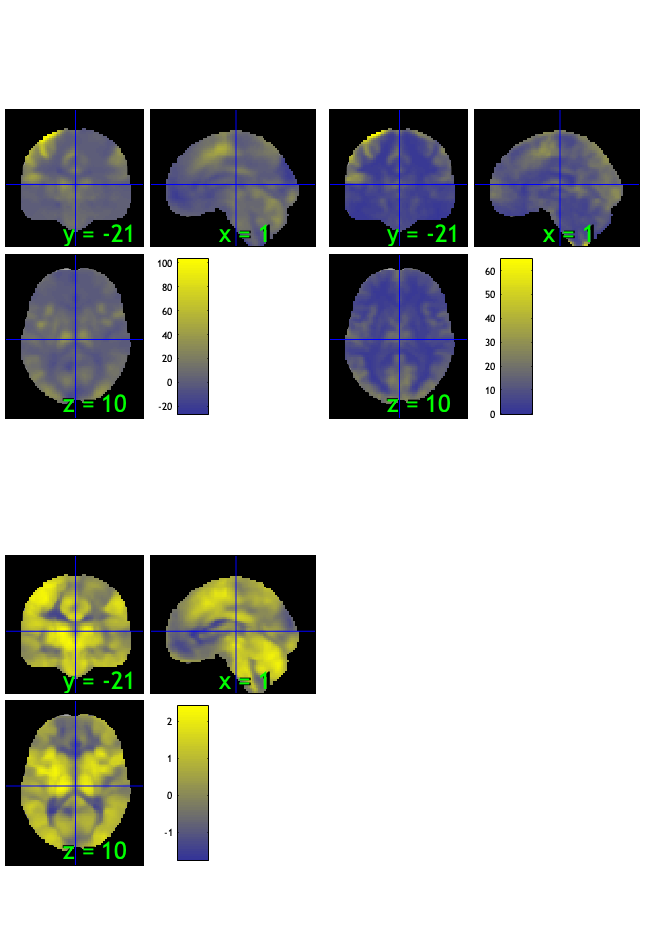

______________________________________________________________
Outlier analysis
______________________________________________________________
global mean | global mean to var | spatial MAD | Missing values |   0 images 


Retained 3 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 38.10%
Expected 4.20 outside 95% ellipsoid, found   5

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 1 images		Cases 44 
Uncorrected: 5 images		Cases 3 12 24 29 44 

Retained 5 components for mahalanobis distance
Expected 50% of points within 50% normal ellipsoid, found 46.43%
Expected 4.20 outside 95% ellipsoid, found   5

Potential outliers based on mahalanobis distance:
Bonferroni corrected: 0 images		Cases  
Uncorrected: 5 images		Cases 9 19 58 69 78 

Mahalanobis (cov and corr, q<0.05 corrected):
  1 images 
                               Outlier_count    Percentage
                               

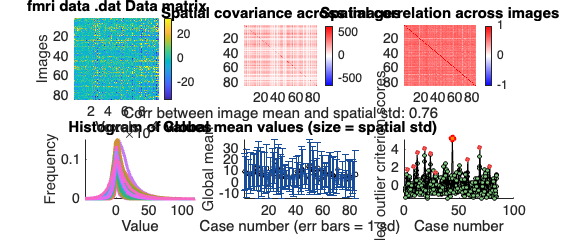

SPM12: spm_check_registration (v7759)              12:34:33 - 24/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1
 (all)  

drawnow; snapnow;

[wh_outlier_uncorr, wh_outlier_corr] = plot(con_data_obj);

#### motor only :: run robfit

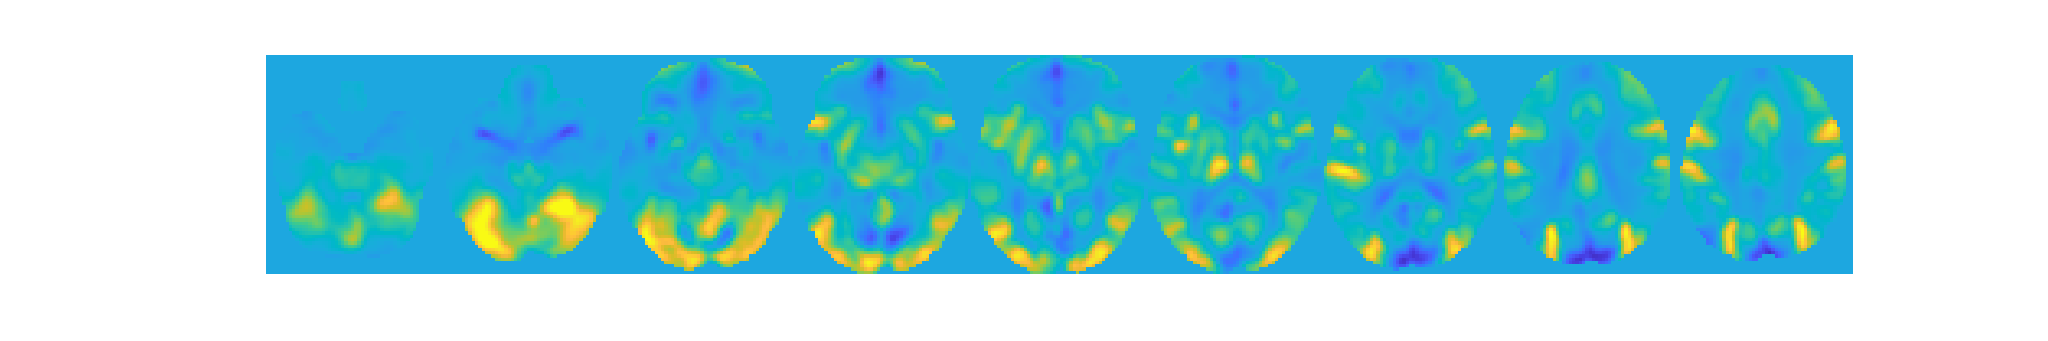

set(gcf,'Visible','on');

figure ('Visible', 'on');
drawnow, snapnow;

#### motor only :: remove outliers based on plot

con = con_data_obj;
disp(strcat("current length is ", num2str(size(con_data_obj.dat,2))));

current length is 84


%for s = 1:length(wh_outlier_corr)
   % disp(strcat("-------subject", num2str(s), "------"))
con.dat = con_data_obj.dat(:,~wh_outlier_corr);
con.image_names = con_data_obj.image_names(~wh_outlier_corr,:);
con.fullpath = con_data_obj.fullpath(~wh_outlier_corr,:);
con.files_exist = con_data_obj.files_exist(~wh_outlier_corr,:);
%end
disp(strcat("after removing ", num2str(sum(wh_outlier_corr)), " participants, size is now ",num2str(size(con.dat,2))));

after removing 1 participants, size is now 83


[path,n,e] = fileparts(con_fldr(wh_outlier_corr));
disp(strcat("participants that are outliers:... ", n));

participants that are outliers:... sub-0080


disp(n);

sub-0080


#### motor only:: plot diagnostics, after l2norm

imgs2 = con.rescale('l2norm_images');

#### motor only :: ttest

t = ttest(imgs2);

One-sample t-test
Calculating t-statistics and p-values


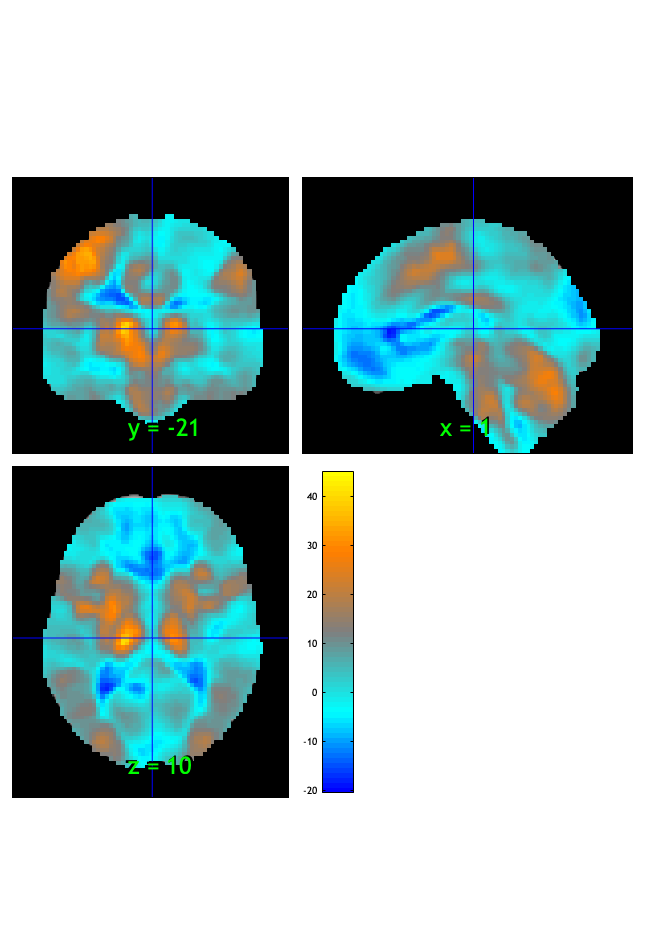

SPM12: spm_check_registration (v7759)              12:34:37 - 24/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


orthviews(t);

drawnow, snapnow;

fdr_t05 = threshold(t, .05, 'fdr');

Image   1 FDR q < 0.050 threshold is 0.041394

Image   1
  6 contig. clusters, sizes   1 to 82648
Positive effect: 65652 voxels, min p-value: 0.00000000
Negative effect: 17018 voxels, min p-value: 0.00000000


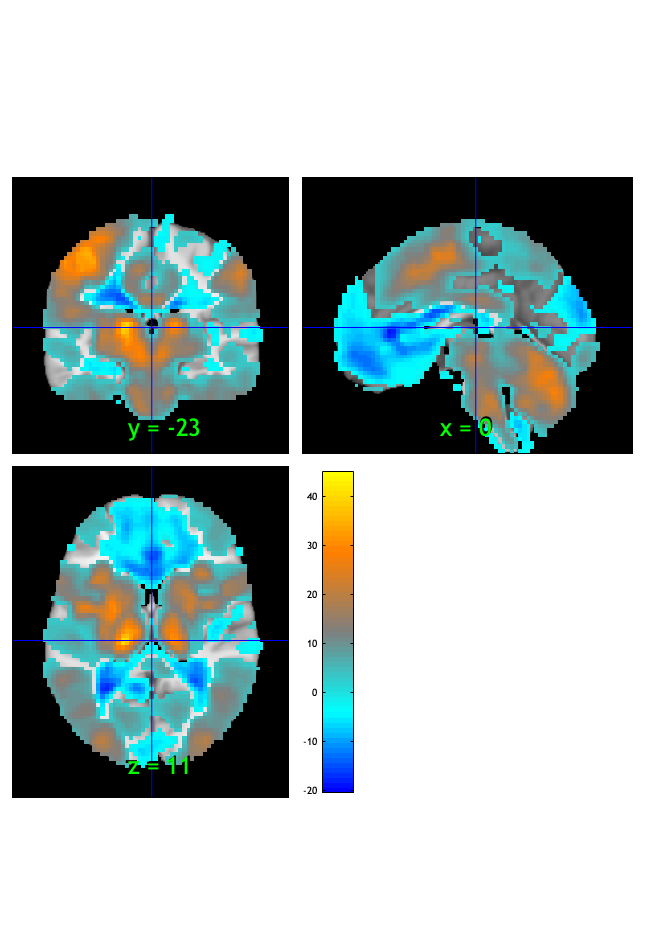

SPM12: spm_check_registration (v7759)              12:34:39 - 24/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


orthviews(fdr_t05);

drawnow, snapnow;
fdr_t05.dat = fdr_t05.dat.*fdr_t05.sig

fdr_t05 =   statistic_image with properties:

              type: 'T'
                 p: [99837×1 single]
            p_type: '2-tailed P-value from input dfe'
               ste: [99837×1 single]
         threshold: 0.0414
          thr_type: []
               sig: [99837×1 logical]
                 N: [99837×1 single]
               dfe: 82
      image_labels: {}
               dat: [99837×1 single]
       dat_descrip: []
           volInfo: [1×1 struct]
    removed_voxels: [99837×1 logical]
    removed_images: 0
       image_names: []
          fullpath: ''
       files_exist: 0
           history: {'Checked image files exist. All exist =   0'  'removed   0 empty voxels and   0 empty images'}


write(fdr_t05, 'fname', fullfile(nifti_save_dir, strcat(nifti_save_fname_prefix, contrast_of_interest, '_fdr-05.nii')), 'overwrite');

Writing: 
/Users/h/Documents/projects_local/cue_expectancy/analysis/fmri/spm/univariate/model01_6cond_ttl/2ndlevel/ttl1_6cond_stimlinear_dummy_motor_fdr-05.nii



fdr_t001 = threshold(t, .001, 'fdr');

Image   1 FDR q < 0.001 threshold is 0.000717

Image   1
 15 contig. clusters, sizes   1 to 71427
Positive effect: 59214 voxels, min p-value: 0.00000000
Negative effect: 12458 voxels, min p-value: 0.00000000


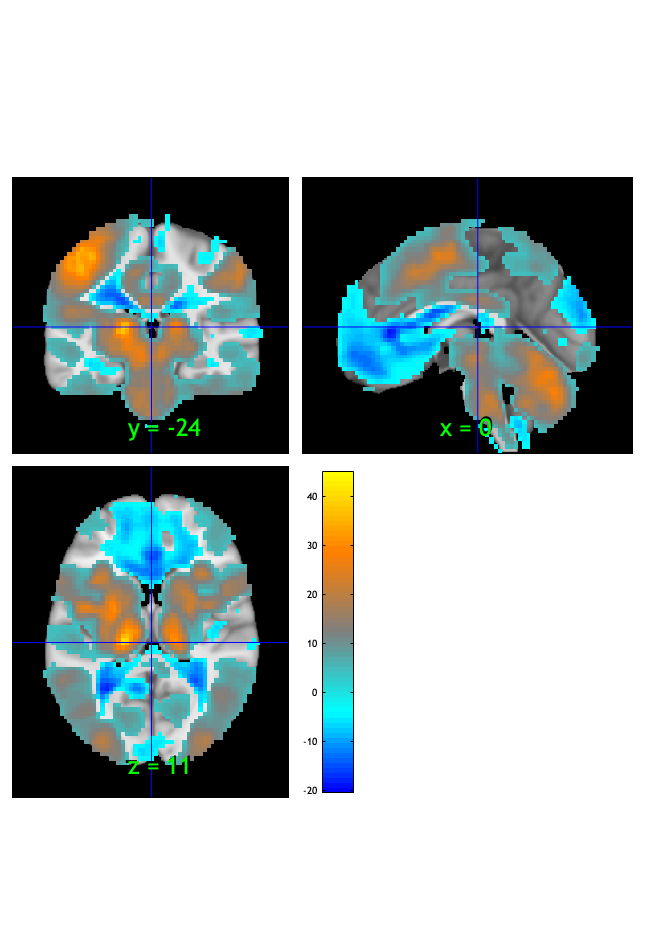

SPM12: spm_check_registration (v7759)              12:34:40 - 24/10/2023
Display /Users/h/Documents/MATLAB/CanlabCore/CanlabCore/canlab_canonical_brains/Canonical_brains_surfaces/keuken_2014_enhanced_for_underlay.img,1


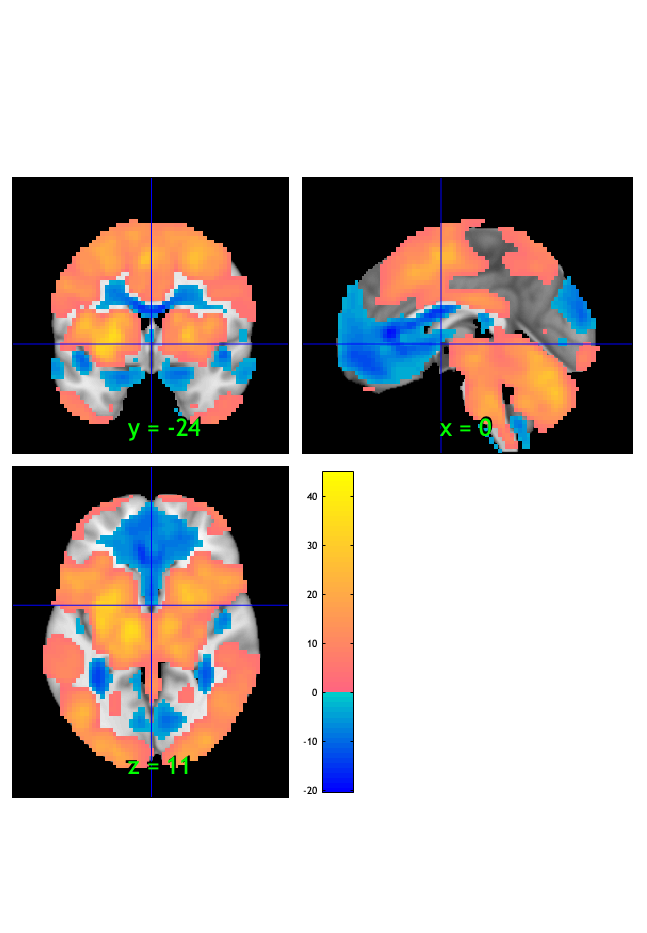

orthviews(fdr_t001);

drawnow, snapnow;
fdr_t001.dat = fdr_t001.dat.*fdr_t001.sig

fdr_t001 =   statistic_image with properties:

              type: 'T'
                 p: [99837×1 single]
            p_type: '2-tailed P-value from input dfe'
               ste: [99837×1 single]
         threshold: 7.1740e-04
          thr_type: []
               sig: [99837×1 logical]
                 N: [99837×1 single]
               dfe: 82
      image_labels: {}
               dat: [99837×1 single]
       dat_descrip: []
           volInfo: [1×1 struct]
    removed_voxels: [99837×1 logical]
    removed_images: 0
       image_names: []
          fullpath: ''
       files_exist: 0
           history: {'Checked image files exist. All exist =   0'  'removed   0 empty voxels and   0 empty images'}


write(fdr_t001, 'fname', fullfile(nifti_save_dir, strcat(nifti_save_fname_prefix, contrast_of_interest, '_fdr-001.nii')), 'overwrite');

Writing: 
/Users/h/Documents/projects_local/cue_expectancy/analysis/fmri/spm/univariate/model01_6cond_ttl/2ndlevel/ttl1_6cond_stimlinear_dummy_motor_fdr-001.nii


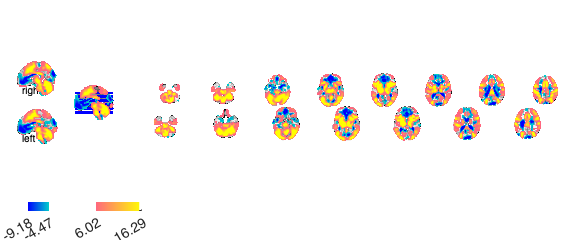

Setting up fmridisplay objects
sagittal montage: 1758 voxels displayed, 69914 not displayed on these slices
sagittal montage: 1748 voxels displayed, 69924 not displayed on these slices
sagittal montage: 1662 voxels displayed, 70010 not displayed on these slices
axial montage: 13062 voxels displayed, 58610 not displayed on these slices
axial montage: 14470 voxels displayed, 57202 not displayed on these slices



create_figure('montage'); axis off;
montage(fdr_t001);

drawnow, snapnow;

#### motor only :: Neurosynth similarity

[image_by_feature_correlations, top_feature_tables] = neurosynth_feature_labels( mean(imgs2), 'images_are_replicates', false, 'noverbose');

Input image 1
fullpath_was_empty
_____________________________________________________________________
    testr_low      words_low       testr_high       words_high   
    _________    ______________    __________    ________________

    -0.34432     {'trait'     }     0.39148      {'movements'   }
     -0.3305     {'positive'  }      0.3677      {'execution'   }
    -0.32973     {'negative'  }     0.35944      {'hand'        }
    -0.31539     {'age'       }     0.33883      {'motor'       }
    -0.30833     {'personal'  }     0.32622      {'visual'      }
    -0.29969     {'depression'}     0.31916      {'finger'      }
    -0.29526     {'emotion'   }      0.2923      {'sensorimotor'}
    -0.29454     {'person'    }     0.28901      {'action'      }
    -0.29416     {'disorder'  }     0.28784      {'hands'       }
    -0.29164     {'affect'    }   

motor only **:: Pattern Phil**

[obj, names] = load_image_set('pain_cog_emo');

Loaded images:
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pMCC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_aMCC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_pACC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_sgACC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_vmPFC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_dMFC_Pain.nii
/Users/h/Documents/MATLAB/Neuroimaging_Pattern_Masks/Multivariate_signature_patterns/2018_Kragel_MFC_Generalizability/bPLS_MFC_Pain.nii
/Users/h/Documents/MATLAB

bpls_wholebrain = get_wh_image(obj, [8 16 24]);
names_wholebrain = names([8 16 24]);
create_figure('Kragel Pain-Cog-Emo maps', 1, 3);

stats = image_similarity_plot(con_data_obj, 'average', 'mapset', bpls_wholebrain, 'networknames', names_wholebrain, 'nofigure');

Table of correlations Group:1
--------------------------------------
T-test on Fisher's r to Z transformed point-biserial correlations
 	R_avg	T	P	sig	
Pain Wholebrain	-0.0181	-4.5639	0.0000	1.0000	
Cog Wholebrain	0.0305	13.0772	0.0000	1.0000	
Emo Wholebrain	-0.0102	-2.6104	0.0107	1.0000	
 


axis image

subplot(1, 3, 2)

barplot_columns(stats.r', 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P         Cohens_d
    ___________________    __________    _________    _______    __________    ________

    {'Pain Wholebrain'}    -0.018062     0.0039573    -4.5643    1.7191e-05    -0.49801
    {'Cog Wholebrain' }     0.030509     0.0023311     13.088    2.2204e-15       1.428
    {'Emo Wholebrain' }    -0.010229     0.0039174    -2.6113      0.010703    -0.28491



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {84×3 cell}
        text_han: {84×3 cell}
       point_han: {84×3 cell}
    star_handles: [13.0009 14.0009 15.0009]


set(gca, 'FontSize', 14)
ylabel('Pattern similarity (r)');
title('Similarity (r) with patterns')

test_data_obj = resample_space(con_data_obj, bpls_wholebrain);

clear csim
for i = 1:3

    csim(:, i) = canlab_pattern_similarity(test_data_obj.dat, bpls_wholebrain.dat(:, i), 'cosine_similarity');

end

Number of zero or NaN values within weight mask, by input image:
 83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83 
Number of zero or NaN values within weight mask, by input image:
 83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83  83


subplot(1, 3, 3)

barplot_columns(csim, 'nofigure', 'colors', {[1 .9 0] [.2 .2 1] [1 .2 .2]}, 'names', names_wholebrain)

Col   1: Pain Wholebrain	Col   2: Cog Wholebrain	Col   3: Emo Wholebrain	
---------------------------------------------
Tests of column means against zero
---------------------------------------------
           Name            Mean_Value    Std_Error       T           P         Cohens_d
    ___________________    __________    _________    _______    __________    ________

    {'Pain Wholebrain'}    -0.013415     0.0035724    -3.7553    0.00032038    -0.40973
    {'Cog Wholebrain' }     0.027693     0.0021374     12.956    2.2204e-15      1.4137
    {'Emo Wholebrain' }    -0.012661     0.0035738    -3.5427    0.00065307    -0.38654



ans = struct with fields:
         fig_han: [1×1 struct]
        axis_han: [1×1 Axes]
        bar_han1: [1×1 Bar]
         bar_han: {[1×1 Bar]  [1×1 Bar]  [1×1 Bar]}
    errorbar_han: {[1×1 ErrorBar]  [1×1 ErrorBar]  [1×1 ErrorBar]}
      point_han1: {84×3 cell}
        text_han: {84×3 cell}
       point_han: {84×3 cell}
    star_handles: [16.0009 17.0009 18.0009]


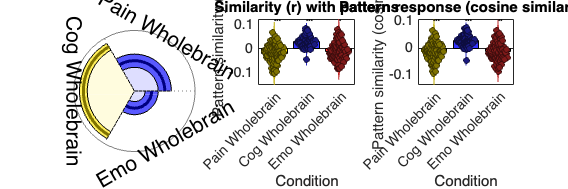

set(gca, 'FontSize', 14)
ylabel('Pattern similarity (cosine sim)');
title('Pattern response (cosine similarity)')

drawnow, snapnow;


% save html
% pubdir = pwd;
% pubfilename = '6cond_cueeffect_contrast.mlx';
% 
% p = struct('useNewFigure', false, 'maxHeight', 800, 'maxWidth', 800, ...
%   'format', 'html', 'outputDir', pubdir, ...
%   'showCode', true, 'stylesheet', which('mxdom2simplehtml_CANlab.xsl'));
% htmlfile = publish(pubfilename, p);